# PROJECT 2 - SOUND TECH

# Συντάκτες: Γιώργος Τοκατλίδης (58352)

#                   Μιχάλης Τσακίρογλου (58486)   

### Αναγνώριση Μουσικών Οργάνων

#### `α) Εξαγωγή Συντελεστών LPC`

`Οι ``LPC`` συντελεστές περιμένουμε να έχουν διαστάσεις για κάθε ηχητικό σήμα nxm, όπου `

`     n``:``το πλήθος των επιθυμητών συντελεστών`` και `

`     m``: ``ο συνολικός αριθμός frames του σήματος``, του οποίου αναλύονται στον πίνακα Χ.`

`Άρα σε κάθε στήλη (frame) του a για αυτό το παράδειγμα, έχουμε μια 30-αδα συντελεστών, με τους οποίους αποπειράται να περιγραφεί ένα διακριτό σήμα με βάση παρελθοντικές τιμές του πολλαπλασιασμένες με τους συντελεστές ai, εξού και η ονομασία της μεθόδου "Γραμμικής Πρόβλεψης". `

`Αυτοί οι συντελεστές πρέπει να ελαχιστοποιούν το σφάλμα που εισάγεται για την επιτυχή αναπαραγωγή ενός ηχητικού σήματος`

clear; 
clc;

frame = 256;
ovrlp = 0.25;
p = 29; 

[x1 Fs] = audioread("voice.wav");
X1 = frame_wind(x1, frame, ovrlp);

[a g] = LPC_Factor_Calc(X1,p);


#### `β) Εξαγωγή Συντελεστών MFCC`

H βασική αρχή των συντελεστών MFCC είναι ότι: *«η ενέργεια ενός σήματος ήχου γενικά σε διάφορες περιοχές/ζώνες του φάσματος χαρακτηρίζουν την ταυτότητα αυτού του σήματος». *Τα βήματα που ακολουθεί ο αλγόριθμος MFCC είναι ο εξής: 

1) Χωρίζει το ηχητικό σήμα σε μικρά πλαίσια με κάποια επικαλυψη

2) Χρησιμοποεί τον DFT( Discrete Fourier Transform) για να μετατρέψει το σήμα από το πεδίο του χρόνου στο πεδίο της συχνότητας. Επειδή για τα ηχητικά σήματα η ανάλυση στο συχνότητας είναι πιο εύκολη απ' ότι στο πεδίο του χρόνου

3) Περιορισμός του Εύρους Τιμών του Πλάτους DFT => Λογαρίθμιση. Διότι το ανθρώπινο αυτί δεν έχει την ίδια ευαισθησία σε όλο το φάσμα συχνοτήτων. Έτσι έχουμε περισσότερη ανάλυση στις χαμηλές Συχνότητες και μικρότερη ανάλυση στις υψηλές συχνότητες.

4) Εφαρμογή κλίμακας συχνοτήτων Mel. 

5) Εφαρμογή φίλτρων για το υπολογισμό της ενέργειας σε διάφορες ζώνες συχνοτήτων.

6) Συμπίεση εξαγώμενης πληροφορίας

Η ρουτίνα mfcc δέχεται τρεις εισόδους το x2, το Fs και το NumCoeffs το οποίο χρησιμοποιούμαι για να εξάγουμε τον επιθυμτό αριθμό συντελεστών και όχι τον προκαθορισμένο σύμφωνα με την ρουτίνα. 

[x2 Fs] = audioread("piano.wav");
MFCC = mfcc(x2, Fs, 'NumCoeffs',29);

#### `γ) Αναγνώριση Μουσικών Οργάνων με συντελεστές MFCC με χρήση προτύπων` 

**Μέθοδος Α** **:** Πρότυπο Όργανο - Διάνυσμα

Βρίσκουμε το μέσο διάνυσμα mi για κάθε όργανο το οποίο είναι ο μέσος όρος κάθε στήλης από τους πίνακες MFCC. Η κάθε στήλη δίνει τη μέση ενέργεια που θα φέρει η πληροφορία του μουσικού οργάνου σε συγκεκριμένη συχνότητα.

Η κατασκευή των μέσων διανυσμάτων mi, των πινάκων MFCC και i, κατασκευάζονται με την λογική ότι μπορεί κάποιος χρήστης να θέλει να εντάξει κάποιο νεό μουσικό όργανο στη λίστα. Για κάθε νέα προσθήκη θα γινόταν και append των πινάκων αυτών. Έτσι, είναι σοφό να έχουμε χρήσιμες-για-τα-όργανα πληροφορίες, όπως αυτές, αποθηκευμένες σε έναν πίνακα "τράπεζα" τον οποίο μεταχειριζόμαστε πιο εύκολα, από το να γεμίζει ο κώδικας με επανάληψη εντολών γραμμή προς γραμμή και με περιττές μεταβλητές και ορίσματα σε συναρτήσεις. Κατά ανάλογο τρόπο, φτιάχνονται και τα si και MFCC.

Η λογική που θα περιγραφεί ακολουθείται σε όλο το πρόγραμμα. Κάθε όργανο έχει ένα index.Στη δικιά μας περίπτωση το πιάνο είναι το 1ο όργανο της λίστας μας, το φλάουτο 2ο, το τσέλο 3ο και η κιθάρα 4η. Αυτά τα index θα ανταποκρίνονται, κάπως και στην κατασκευή των πινάκων, δηλαδή:

η 1η στήλη ή 1η γραμμή σε έναν πίνακα θα έχει να κάνει με το πρότυπο πιάνο,η 2η στήλη ή 2η γραμμή στον ίδιο πίνακα θα έχει να κάνει με το πρότυπο φλάουτο κ.ο.κ. Με αυτόν τον τρόπο δίνεται και η δυνατότητα scaling της εφαρμογής του προγράμματος.

Παρακάτω αυτή η ιδέα φαίνεται στον κώδικα, με οδηγό τα σχόλια που τον συνοδεύουν.

`(Results-plithos_indices)`

Αποθηκεύουμε όλα τα αποτελέσματα των δειγμάτων στον πίνακα results με την σειρά που ορίζεται από το index των οργάνων. Στην παρακάτω λούπα παράγεται το confusion matrix. 

- Η εξωτερική - ρυθμίζει σε ποια τεστ πραγματικού οργάνου αναφερόμαστε

- Η εσωτερική - ανατρέχει τα αντίστοιχα αποτελέσματα των τεστ του οργάνου απο τη συνάρτηση, και μετράει πόσα 1,2,3 και 4 έχουμε σαν index for minimum distances δηλ, το i όργανο πόσες φορές αναγνωρίστηκε σαν το j = 1ο,2ο,..., i-οστο,..., n-οστο (αυτό επιτυγχάνεται με την έκφραση στο δεξί μέλος).

[x_piano Fs] = audioread("piano_samples.wav");
[x_flute Fs] = audioread("flute_samples.wav");
[x_cello Fs] = audioread("cello_samples.wav");
[x_guitar Fs] = audioread("e_guitar_samples.wav");

MFCCpiano = mfcc(x_piano, Fs, 'NumCoeffs',29);
MFCCflute = mfcc(x_flute, Fs, 'NumCoeffs',29);
MFCCcello = mfcc(x_cello, Fs, 'NumCoeffs',29);
MFCCguitar= mfcc(x_guitar, Fs, 'NumCoeffs',29);

n_learning = 4000;
MFCC = [MFCCpiano(1:n_learning,:); MFCCflute(1:n_learning,:); MFCCcello(1:n_learning,:); MFCCguitar(1:n_learning,:)];

**> calculate mean-vector mi - Instrument i **

temp = [1:n_learning];
for i = 1:4
    mi(i,:) = mean(MFCC(temp,:));
    temp = temp + n_learning;
end


**> Get the different indexes of minimum distances that correspond to different**

**> instrument prototypes**

piano_test_results = instrument_recognition(MFCCpiano,mi);
flute_test_results = instrument_recognition(MFCCflute,mi);
cello_test_results = instrument_recognition(MFCCcello,mi);
guitar_test_results = instrument_recognition(MFCCguitar,mi);

results = [piano_test_results;flute_test_results;cello_test_results;guitar_test_results];

for i=1:4
    for j=1:4
    plithos_indices(i,j) = sum(results(i,:)==j);
    end
    
end
 plithos_indices

plithos_indices =    283     0     0     0
     0   194    54    35
     0     0   283     0
     0     0    19   264


**> plot the confusion matrix of plithos_indices**

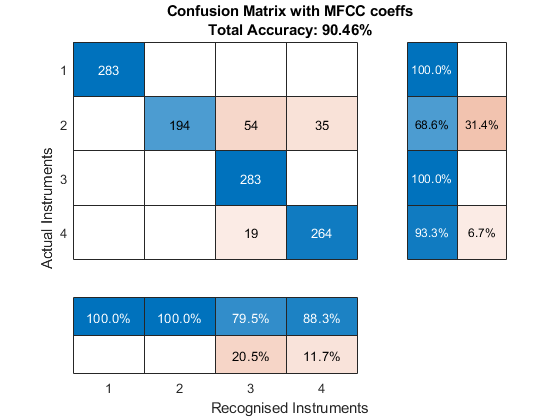

figure();
cm = confusionchart(plithos_indices);

cm.XLabel = 'Recognised Instruments';
cm.YLabel = 'Actual Instruments';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

totalAccuracy = sum(diag(plithos_indices)) / sum(plithos_indices(:));

% Add the total accuracy to the confusion chart
cm.Title = sprintf('Confusion Matrix with MFCC coeffs\nTotal Accuracy: %.2f%%', totalAccuracy*100);

#### `δ) Αναγνώριση Μουσικών Οργάνων με συντελεστές MFCC με χρήση Γκαουσιανής κατανομής`

Για την si η μόνη ιδιαιτερότητα της είναι ως προς το πως θα μεταχειριστούμε

index της, γνωρίζοντας τις διαστάσεις του όπως και τις διαστάσεις του MFCC.

Αυτή τη δουλειά ακριβώς επιτελούν οι μεταβλητές temp1 & temp2.

- Για κάθε όργανο ο πίνακας συνδιασποράς θα είναι τετραγωνικός με διαστάσεις που ορίζονται από το πλήθος των συντελεστών mi. Άρα σε κάθε iteration (όπου ρυθμίζεται σε ποιο πρότυπο όργανο αναφερόμαστε)                 θα πρέπει να αλλάζει ο δείκτης temp2 κατά 30 (n_of_coeffs). 

- Αντίστοιχη συλλογιστική ακολουθείται και για το index temp1 που αφορά την MFCC μέσα στο for-loop.

**> Calculate the covariance matrix**

n_of_coeffs = size(mi,2);
temp1 = [1:n_learning];
temp2 = [1:n_of_coeffs];
for i = 1:4
    si(temp2,:) = cov(MFCC(temp1,:));
    temp1 = temp1 + n_learning;
    temp2 = temp2 + n_of_coeffs;
end

**> Calculate the Gaussian distribution of each instrument**

p_piano = PDF(MFCCpiano, mi, si);
p_flute = PDF(MFCCflute, mi, si);
p_cello = PDF(MFCCcello, mi, si);
p_guitar = PDF(MFCCguitar,mi, si);

P = [p_piano; p_flute; p_cello; p_guitar]

P =    279     1     3     0
     1   282     0     0
     0     0   283     0
     0     0     2   281


**> plot the confusion matrix of the probability distribution function **

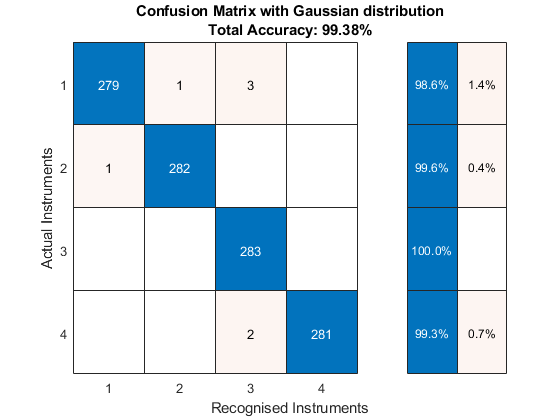

 
figure();
cm = confusionchart(P);

cm.XLabel = 'Recognised Instruments';
cm.YLabel = 'Actual Instruments';

cm.RowSummary = 'row-normalized';
%cm.ColumnSummary = 'column-normalized';

totalAccuracy = sum(diag(P)) / sum(P(:));

% Add the total accuracy to the confusion chart
cm.Title = sprintf('Confusion Matrix with Gaussian distribution\nTotal Accuracy: %.2f%%', totalAccuracy*100);

Είναι φανερό από τις μετρήσεις, πως η συνολική ακρίβεια του συστήματος βελτιώνεται αισθητά με τη μέθοδο της Γκαουσσιανής κατανομής. Η πολύ εμπειρική εξηγήση, ορίζει πως τα κατά το πλείστον πράγματα στη φύση ακολουθούν τη γκαουσσιανή κατανομή. Σε αυτή τη κατηγορία εμπίπτουν και τα μουσικά όργανα. Αυτό επιβεβαιώνεται με το [κεντρικό οριακό θεώρημα](https://el.wikipedia.org/wiki/%CE%98%CE%B5%CF%8E%CF%81%CE%B7%CE%BC%CE%B1_%CE%BA%CE%B5%CE%BD%CF%84%CF%81%CE%B9%CE%BA%CE%BF%CF%8D_%CE%BF%CF%81%CE%AF%CE%BF%CF%85) που διατυπώνεται ως το άθροισμα ενός μεγάλου αριθμού ανεξάρτητων τυχαίων μεταβλητών(mf) που ακολουθεί μία κατανομή η οποία προσεγγίζει την [κανονική κατανομή](https://el.wikipedia.org/wiki/%CE%9A%CE%B1%CE%BD%CE%BF%CE%BD%CE%B9%CE%BA%CE%AE_%CE%BA%CE%B1%CF%84%CE%B1%CE%BD%CE%BF%CE%BC%CE%AE). Συνεπώς, επιτυγχάνουμε μια καλύτερη προσέγγιση του φυσικού φαινομένου.

#### `ε) Σύγκριση συντελεστών LPC με συντελεστές MFCC στην αναγνώριση μουσικών οργάνων`

Λίγα λόγια για LPC vs MFCC βάση παρατηρήσεων και το πρόβλημα της ΛΠΨ για τη μέθοδο γκαουσσσιανής κατανομής.

Φαίνεται πως η LPC υστερεί αισθητά σε σχέση με την MFCC τουλάχιστον στον τομέα της αναγνώρισης μουσικών οργάνων. Ένα μεγάλο πρόβλημα επίσης της LPC είναι πως οι συντελεστές a1-δηλαδή ο "πιο παρελθοντικός συντελεστής" κάθε frame, είναι ίσοι με 1.

Aυτό έχει σαν συνέπεια η συνδιασπορά του a1 να είναι μηδενική, με αποτέλεσμα να αποτυγχάνει η μέθοδος της Γκαουσιανής κατανομής, αφού έχουμε για τον υπολογισμό της πιθανότητας παρονομαστή ίσο με το 0.

%%--Same Implementation using LPC coefficients--

Xpiano = frame_wind(x_piano, frame, ovrlp);
Xflute = frame_wind(x_flute, frame, ovrlp);
Xcello = frame_wind(x_cello, frame, ovrlp);
Xguitar = frame_wind(x_guitar, frame, ovrlp);

a_piano = LPC_Factor_Calc(Xpiano,p);
a_flute = LPC_Factor_Calc(Xflute,p);
a_cello = LPC_Factor_Calc(Xcello,p);
a_guitar = LPC_Factor_Calc(Xguitar,p);

a_piano(:,4284:14796) = [];
a_flute(:,4284:14796) = [];
a_cello(:,4284:14796) = [];
a_guitar(:,4284:14796) = [];

a_piano = a_piano';
a_flute = a_flute';
a_cello = a_cello';
a_guitar = a_guitar';

a = [a_piano; a_flute; a_cello; a_guitar];

%calculate mean-vector mi - Instrument ID
temp = [1:n_learning];
for i = 1:4
    mi(i,:) = mean(a(temp,:));
    temp = temp + n_learning;
end

%Get the different indexes of minimum distances that correspond to different 
%instrument prototypes
piano_test_results = instrument_recognition(a_piano,mi);
flute_test_results = instrument_recognition(a_flute,mi);
cello_test_results = instrument_recognition(a_cello,mi);
guitar_test_results = instrument_recognition(a_guitar,mi);

results = [piano_test_results;flute_test_results;cello_test_results;guitar_test_results];

for i=1:4
    for j=1:4
    plithos_indices_GD(i,j) = sum(results(i,:)==j);
    end
    
end

plithos_indices_GD

plithos_indices_GD =    282     0     0     1
     0   232    46     5
     0   240    31    12
     4     0    55   224


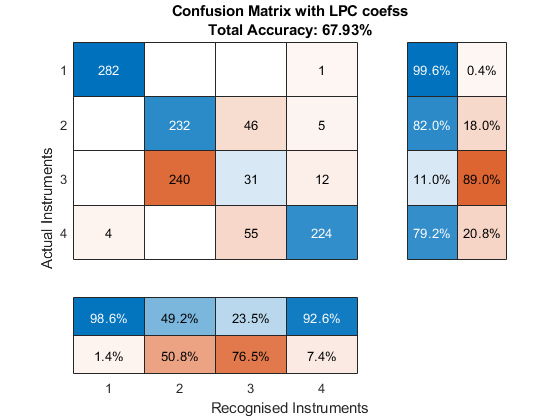


figure();
cm = confusionchart(plithos_indices_GD);

cm.XLabel = 'Recognised Instruments';
cm.YLabel = 'Actual Instruments';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

totalAccuracy = sum(diag(plithos_indices_GD)) / sum(plithos_indices_GD(:));

% Add the total accuracy to the confusion chart
cm.Title = sprintf('Confusion Matrix with LPC coefss\nTotal Accuracy: %.2f%%', totalAccuracy*100);


% Calculate the covariance matrix

n_of_coeffs = size(mi,2);
temp1 = [1:n_learning];
temp2 = [1:n_of_coeffs];
for i = 1:4
    si(temp2,:) = cov(a(temp1,:));
    temp1 = temp1 + n_learning;
    temp2 = temp2 + n_of_coeffs;
end

%because the 1st LPC factor of each instrument has zero covariance
%mvnpdf fails as a routine to calculcate the probability p.
p_piano = PDF(a_piano, mi, si);

Error using mvnpdf (line 129)
SIGMA must be a square, symmetric, positive definite matrix.

Error in presentation>PDF (line 212)
        P(j) = mvnpdf(mf(i,:), mi(j,:), si(temp:j*si_jump,:));


% p_flute = PDF(a_flute, mi, si);
% p_cello = PDF(a_cello, mi, si);
% p_guitar = PDF(a_guitar,mi, si);
% 
% 
% P = [p_piano; p_flute; p_cello; p_guitar]
% 
% figure();
% cm = confusionchart(P);
% 
% cm.XLabel = 'Recognised Instruments';
% cm.YLabel = 'Actual Instruments';
% 
% cm.RowSummary = 'row-normalized';
% %cm.ColumnSummary = 'column-normalized';
% 
% totalAccuracy = sum(diag(P)) / sum(P(:));
% 
% % Add the total accuracy to the confusion chart
% cm.Title = sprintf('Confusion Matrix\nTotal Accuracy: %.2f%%', totalAccuracy*100);

# Οι συναρτήσεις που χρησιμοποιήθηκαν:

Η ρουτίνα **“frame_wind” **διαιρεί μια κυματομορφή ήχου σε μικρότερα παράθυρα με επικάλυψη. Η ρουτίνα παίρνει ως μεταβλητές εισόδου i) τη διακριτή κυματομορφή ήχου x, ii) το μέγεθος του παραθύρου σε πλήθος δειγμάτων frame, iii) το ποσοστό του παραθύρου στο οποίο θα γίνεται η επικάλυψη ovrlp (από 0 ως 1, default = 0.5). H έξοδος της ρουτίνας είναι ένας πίνακας X, κάθε στήλη του οποίου περιέχει τα παράθυρα που έχουμε εξάγει με τη σειρά εξαγωγής.

function X=frame_wind(x,frame, ovrlp)   
    M=length(x);
    K=floor(M/(frame*ovrlp));
    X=zeros(frame,K);
    W=hann(frame);
    for i=1:K-floor(1./ovrlp-1)
        indx=(i-1)*floor(frame*ovrlp);
        X(:,i)=x(indx+1:indx+frame).*W;
    end
end 

Η ρουτίνα **"PDF" **μοντελοποιεί τη συνάρτηση πυκνότητας πιθανότητας της  γκαουσιανής κατανομής έτσι ώστε να μας δώσει τη πιθανότητα ένα συγκεκριμένο διάνυσμα MFCC να ανήκει σε κάθε μουσικό όργανο. Η συνάρτηση πυκνότητας πιθανότητας δίνεται από την ακόλουθη σχέση: $\textrm{𝑝}\left(\textrm{𝒎𝒇},{\textrm{𝒎}}_{\mathit{\mathbf{i}}} ,\Sigma_{\mathit{\mathbf{i}}} \right)=\frac{1}{\;\sqrt{2\pi \left|\Sigma_{\mathit{\mathbf{i}}} \right|}}\exp \left(-0\ldotp 5*{\left(\textrm{𝒎𝒇}-{\textrm{𝒎}}_{\mathit{\mathbf{i}}} \right)}^T *{\left(\Sigma_i \right)}^{-1} *\left(\textrm{𝒎𝒇}-{\textrm{𝒎}}_{\mathit{\mathbf{i}}} \right)\right)$

Για απλοποίηση του κώδικα μας επιλέξαμε να αξιοποιήσουμε την εντολή του MATLAB `mvnpdf.`

**> Ορίσματα συνάρτησης: **

- mf:  συντελεστές MFCC.

- mi: τα συσσωρευμένα διανύσματα μέσης τιμής για το κάθε όργανο.

- si: οι συσσωρευμένοι πίνακες συνδιασποράς για το κάθε όργανο.

Output:

- p: ένας πίνακας πιθανοτήτων με μέγεθος nxn,όπου κάθε γραμμή περιέχει την πιθανότητα ένα διάνυσμα MFCC να ανήκει σε κάθε μουσικό όργανο.

Στη συνάρτηση δημιουργούμε ένα πίνακα **p** με διαστάσεις 1 x 4 και θα αποθηκεύσει τις τιμές που  είχαμε επιτυχή και ανεπιτυχή ταυτοποίηση των μουσικών οργάνων και έναν πίνακα **P **ο οποίος χρησιμοποιείται για την αποθήκευση αποτελεσμάτων της συνάρτησης πυκνότητας πιθανότητας(με διαστάσεις 1 x 4 ). Έπειτα εντοπίζουμε τον δείκτη **id** που δείχνει στην μέγιστη τιμή του πίνακα **P**( και έτσι γνωρίζουμε την στήλη που βρίσκεται), και άρα την μεγαλύτερη πιθανότητα από τις 4. Τελος, τοποθετούμε μία μονάδα σε μια θέση του πίνακα **p** που ορίζεται απο την 1η γραμμή και τη στήλη **id**, όπου η μονάδα υποδηλώνει με ποιο όργανο ταυτοποίησε ότι ταιριάζει το διάνυσμα επαλήθευσης.

function p = PDF(mf, mi, si)

n_of_tests = size(mf, 1);
n_instruments = size(mi,1);

p = zeros(1, n_instruments); % with dimensions (1 x 4)

si_jump = size(si,2); % we choose the columns size 
                      % because the si matrices are stacked horizontally

for i =  4001:n_of_tests % We iterate through the test vectors
        
    temp = [1:si_jump]; % we set the temp value back to 1:30, so we dont exeed the array's length
    for j = 1:n_instruments%(1:4)
        P(j) = mvnpdf(mf(i,:), mi(j,:), si(temp:j*si_jump,:));
        temp = temp + si_jump;
    end
    
    [~, id] = max(P);       % we store the id of the max value of 
    p(1, id) = p(1, id) + 1;
end

end


Η ρουτίνα **“LPC_Factor_Calc” **κατασκευάστηκε για τον υπολογισμό των LPC συντελεστών αντί να έχουμε πολλές for-loop μέσα στο πρόγραμμα για το ερώτημα δ).

function [a,g] = LPC_Factor_Calc(X, p)

% X: Matrix that has all the frames stored column-by-column
% p: required number of LPC coefficients

cols = size(X,2);

a=[];
g=[];

for i=1:cols
[A G] = lpc_new(X(:,i), p);
a = [a A];
g = [g G];
end

end


Η ρουτίνα **“lpc_new”  **χρησιμοποιείται για να υπολογίσουμε p = 30 συντελεστές γραμμικής πρόβλεψης ai,t και το αντίστοιχο κέρδος Gt που περιγράφουν το κάθε παράθυρο.

function [a,g]=lpc_new(s,p)
[autos ,lags] = xcorr(s);
autos = autos(find(lags==0):end); 
[a,g] = levinson(autos ,p);
g=sqrt(g);
a=a';
end 


Η ρουτίνα **“instrument_recognition” .**

Οι μεταβλητές που ορίζονται εκτός του for-loop είναι αυτοεπεξηγούμενες.

          Όσον αφορά το for loop: 

- Η πρώτη - εξωτερική λούπα είναι αυτή που τρέχει κάθε δείγμα/τεστ 

- Οι τιμές των αποτελεσμάτων της απόστασης μετακύ προτύπων και τεστ αποθηκέυονται στο instrument_results

- Η ενδιάμεση - δεύτερη λούπα απλά κάνει εφαρμογή του τύπου για την απόσταση

- Για να μην έχουμε στη δεύτερη λούπα 4 ξεχωριστές γραμμές για την σύγκριση του δείγματος με κάθε όργανο (για λόγους αισθητικής και πάνω απ'ολα καθολικότητας του προγράμματος) εισάγουμε μια τρίτη λούπα η οποία ρυθμίζει με ποιο πρότυπο όργανο γίνεται η σύγκριση κάθε φορά.

Έπειτα πρέπει να αποθηκευτεί ποιο πρότυπο όργανο είναι πιο κοντά στο δείγμα μας. Εκμεταλλευόμαστε την δεικτοποίηση που αναφέρθηκε στην αρχή της περιγραφής μας για το **γ)** ερώτημα. Στα σχόλια της συνάρτησης αυτό γίνεται πιο ξεκάθαρο

function [instrument_test_results]  = instrument_recognition(MFCCinstrument, mi)

%testing phase 
%let piano be prototype instrument(or column in the test matrices)
% n.1, flute n.2, cello n.3, guitar n.4 in our example

n_learning = 4000;
n_of_tests = size(MFCCinstrument,1) - n_learning;
n_of_coeffs = size(MFCCinstrument,2);
n_of_instruments = size(mi,1);

for i = (n_learning+1):(n_learning+n_of_tests)
    
    instrument_tests(i,1:n_of_instruments) = 0;
    
    for k = 1:n_of_coeffs
        for j = 1:n_of_instruments
            instrument_tests(i,j) = instrument_tests(i,j) + ( MFCCinstrument(i,k) - mi(j,k) )^2;
        end
    end
    
    instrument_tests(i,:) = sqrt(instrument_tests(i,:));
    
    %distance between a test vector and an instrument-prototype
    %is stored in instrument_tests likewise: 
    %test-prototype_piano(column 1)
    %test-prototype_flute(column 2)
    %test-prototype_cello(column 3)
    %test-prototype_guitar(column 4)
    
    %every row in the test matrices coresponds to a different test
    
    %let's store the column index for every minimum distance in every test
    
    %with all the above we know that 1s' correspond to piano recognitions
    %2s' to flute recognitions etc
    [~, instrument_test_results(i)] = min(instrument_tests(i,:));
    
end

%could have avoided the lines below, by transforming 
%the index of instrument_tests in the for-loop likewise: i -> (i-n_learning)
%but didn't for aesthetic purposes

instrument_tests (1:4000,:) = [];
instrument_test_results (1:4000) = [];

end